# Final Project Matlab Intelligent Control

Amir Hossein Mansouri 9931113

## Particle Swarm Optimization (PSO) Algorithm

clc;
clear; 
close all;

## Examine given plant

s = tf('s');
G = 4.228/((s+0.5)*(s^2+1.64*s+8.456))

G =
 
               4.228
  --------------------------------
  s^3 + 2.14 s^2 + 9.276 s + 4.228
 
Continuous-time transfer function.



pzplot(G)
step(G)
stepinfo(G)

## hyperparameters

%%hyperparameters
c1=2;
c2=2;
w = 0.8;
max_var = 10;
rng(9931123);
num_iterations = 500;
num_particles = 40;
num_dimensions = 3;

s = tf('s');

% Initialize particle positions and velocities
X =  max_var * rand(num_particles, num_dimensions);
V = rand(num_particles, num_dimensions);
% Initialize personal best positions and values
P_best = X;
P_best_value = Fitting_function(X, G, s, num_particles);
% Initialize global best position and value
[G_best_value, G_best_index] = min(P_best_value);
G_best = P_best(G_best_index,:);
for i = 1:num_iterations
    % Update particle velocities and positions
    % Generate random values
    r1 = rand(num_particles, 1);
    r2 = rand(num_particles, 1);

    % Update velocity
    V = w * V + c1 * r1 .* (P_best - X) + c2 * r2 .* (G_best - X);

    % Update position
    X = X + V;

    % Check boundaries
    X = max(0, min(max_var, X));
    
    % Update personal best
    current_values = Fitting_function(X, G, s, num_particles);
    update_mask = current_values < P_best_value;
    P_best_value(update_mask) = current_values(update_mask);
    P_best(update_mask, :) = X(update_mask, :);

    % Update global best

    [min_value, min_index] = min(P_best_value);
    if min_value < G_best_value
        G_best_value = min_value;
        G_best = P_best(min_index,:);
    end
    
 end

% Display the final result
fprintf('\nOptimal Solution:\n');


Optimal Solution:


fprintf('P = %f, I = %f, D = %f\n', G_best(1), G_best(2), G_best(3));

P = 5.440509, I = 10.000000, D = 9.625542


fprintf('Optimal Value = %f\n', G_best_value);

Optimal Value = 0.173038


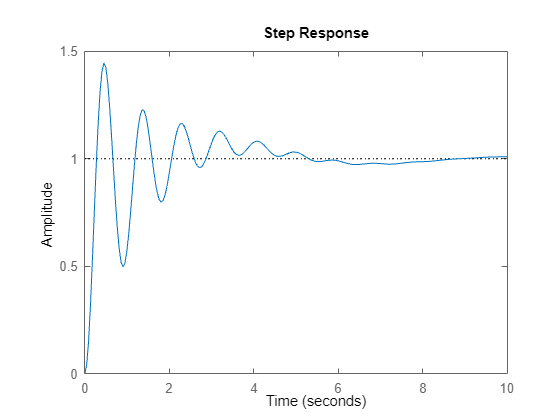


C = G_best(1)+G_best(2)/s+G_best(3)*s;
Gcl = feedback(C*G,1);
step(Gcl)

stepinfo(Gcl)

ans = struct with fields:
         RiseTime: 0.1870
    TransientTime: 7.5426
     SettlingTime: 7.5426
      SettlingMin: 0.4968
      SettlingMax: 1.4451
        Overshoot: 44.5114
       Undershoot: 0
             Peak: 1.4451
         PeakTime: 0.4523


Evaluate_(G_best, G, s)

ans =     0.2702
    0.7999
    1.4198
    0.1730


function out = Fitting_function(X, G, s, num_particles)
    X = X';
    out = zeros(num_particles,1);
    for i = 1:num_particles
        x = X(:,i);
        C = x(1)+x(2)/s+x(3)*s;
        Gcl = feedback(C*G,1);
        [y, t] = step(Gcl);
        %out(i) = trapz(t, (1-y).^2); %ISE
        %out(i) = trapz(t,abs(1-y)); %IAE
        %out(i) = trapz(t, t.*abs(1-y)); %ITAE
        out(i) = trapz(t, t.*(1-y).^2); %ITSE
    end
end

function out = Evaluate_(X, G, s)
    X = X';
    out = zeros(4,1);
    C = X(1)+X(2)/s+X(3)*s;
    Gcl = feedback(C*G,1);
    [y, t] = step(Gcl);
    out(1) = trapz(t, (1-y).^2); %ISE
    out(2) = trapz(t,abs(1-y)); %IAE
    out(3) = trapz(t, t.*abs(1-y)); %ITAE
    out(4) = trapz(t, t.*(1-y).^2); %ITSE
end